clearvars

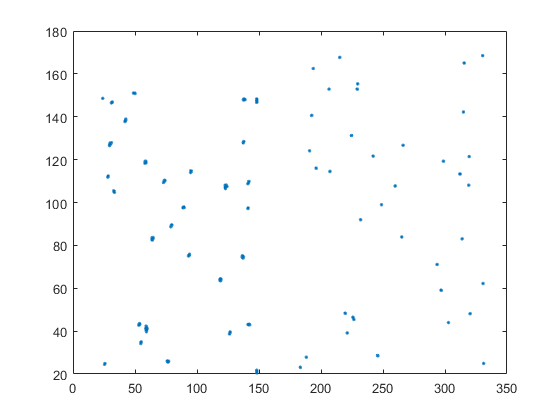

files = dir('*dast*'); % List calibration data files
% allocate arrays for building
xf = [];
yf = [];
N = [];
fnum = [];
mean_xf = [];
mean_yf = [];
zf = [];
% load calibration data and store in conglomorate array
colors = {'red','orange'};
X = [];
Z = [];
Y = [];
clus_num = [];
similar_file = [];
for i = 1:numel(files)
    load(files(i).name)
    for j = 1:2
        if j == 1
            index = cdata.(colors{j}).zf < 0.7 & cdata.(colors{j}).zf > -0.5;
        else
            index = cdata.(colors{j}).zf < 0.75 & cdata.(colors{j}).zf > -0.5;
        end
%         xf = [xf; cdata.(colors{j}).fits(index,1)];
%         yf = [yf; cdata.(colors{j}).fits(index,2)];
    % Choose to work in pixel space
        xf = [xf; cdata.(colors{j}).xf(index)/q];
        yf = [yf; cdata.(colors{j}).yf(index)/q];
        zf = [zf; cdata.(colors{j}).zf(index)/q];
        
        N = [N; cdata.(colors{j}).fits(index,3)];
        
        % Current file's x-y
%         xf_p = cdata.(colors{j}).fits(index,1);
%         yf_p = cdata.(colors{j}).fits(index,2);
        xf_p = cdata.(colors{j}).xf(index)/q;
        yf_p = cdata.(colors{j}).yf(index)/q;
        zf_p = cdata.(colors{j}).zf(index)/q;
        
        fnum = [fnum; cdata.(colors{j}).framenumber(:) + max([max(fnum),0])];
        
        % Average over data on each frame as it comes in
        added = xf_p*0;

        for k = 1:numel(xf_p)
            if added(k) == 0
                dist = ((xf_p-xf_p(k)).^2 + (yf_p-yf_p(k)).^2 ).^0.5;
                ind = dist < 1;
                if j == 1
                    ind = ind & xf_p > 23.53 & xf_p < 148.34;
                end
                X = [X;mean(xf_p(ind))];
                Y = [Y;mean(yf_p(ind))];
                Z = [Z;mean(zf_p(ind))];
                similar_file = [similar_file;i];
                clus_num = [clus_num;sum(ind)];
                added(ind) = 1;
            end
        end
    end
end

% plot(xf_p,yf_p,'.')
index = clus_num > 20;
X = X(index);
Y = Y(index);
similar_file = similar_file(index);
plot(X,Y,'.')
hold off

% User seed selection section
% User will do the first overlay approximation
file = 2;
files(file).name

ans = 'channel_2_dast.mat'

load(files(file).name)
files(file).name(1:end-9)

ans = 'channel_2'

image_name = [files(file).name(1:end-9),'.tif']

image_name = 'channel_2.tif'

image_location = pwd;
image_location = image_location(1:end-8)

image_location = 'G:\Dropbox\Data\3-30-21 calibration\'

image = readtiff([image_location,image_name]);
mean_image = mean(image,3);
clims = [ 0 max(mean_image(:))*0.5];

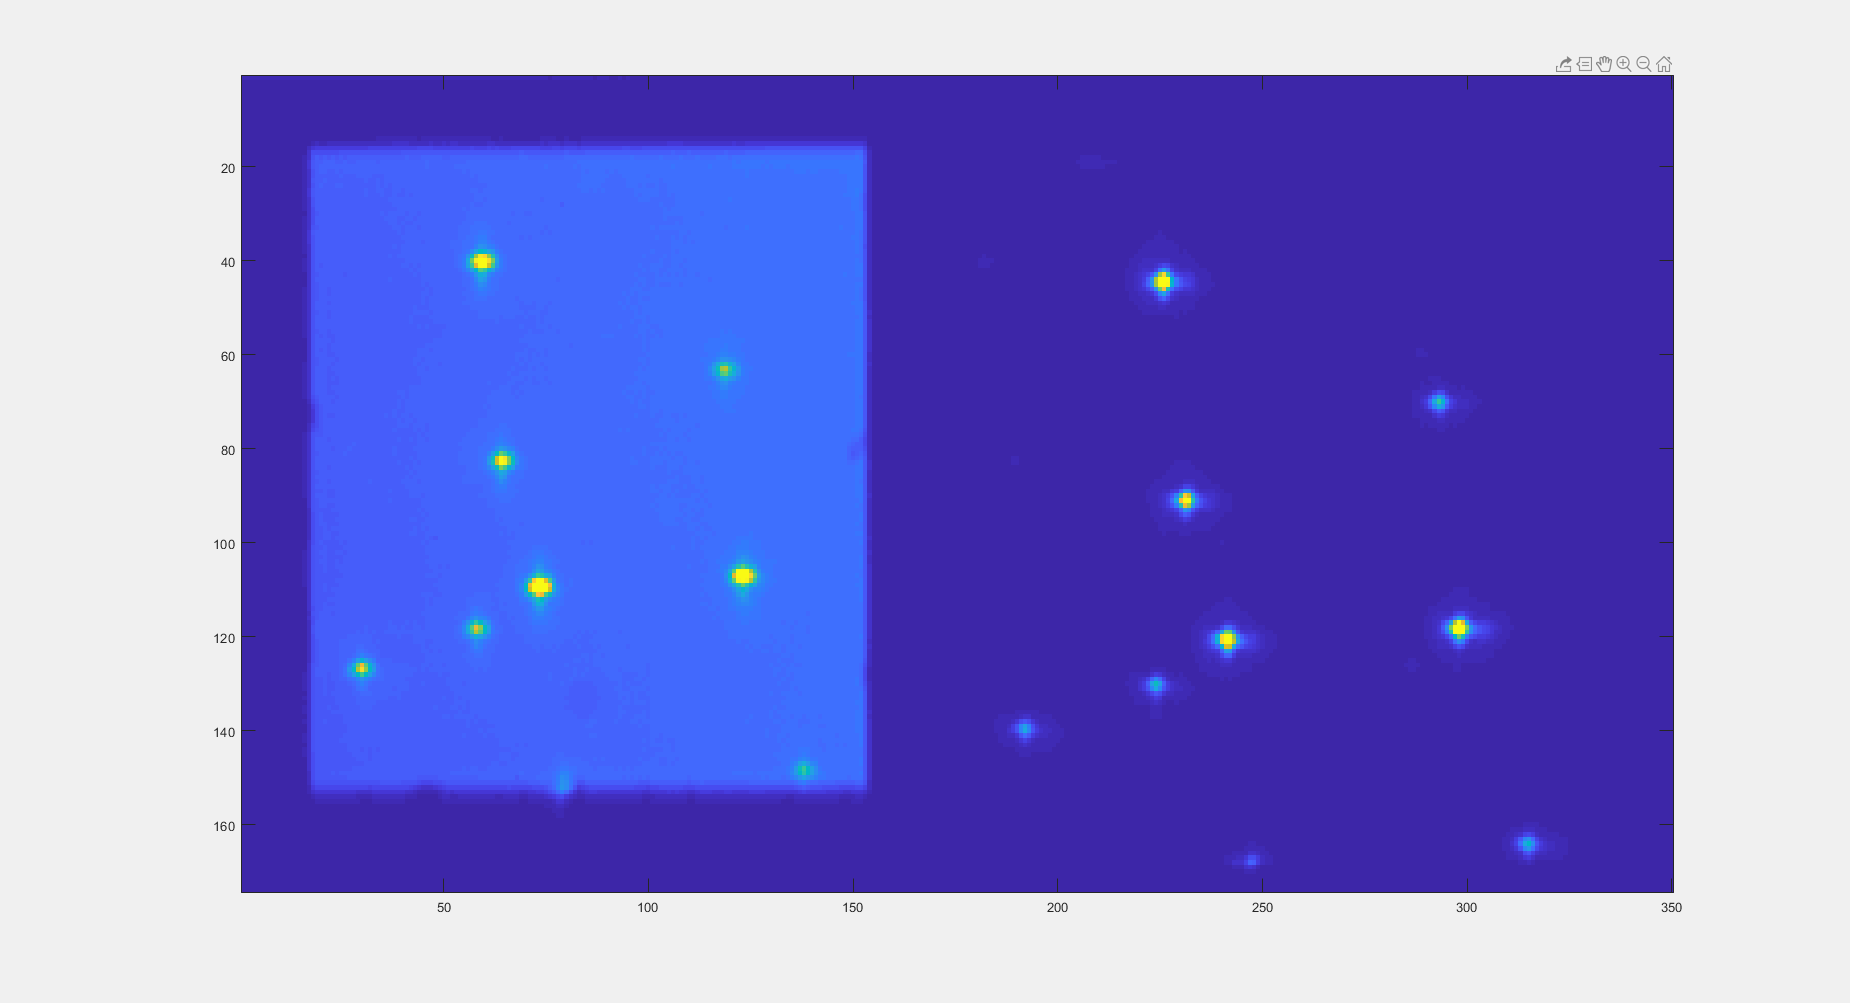

x =    59.4846
  226.3025
  118.8357
  293.7135
   64.3695
  231.4316
   30.1755
  192.3528
   57.7749
  224.1043


y =    40.1711
   44.8509
   63.7824
   69.9511
   82.9267
   91.2225
  126.7457
  139.9340
  118.0244
  130.5746


% We need to satify the number of independent variables in the
% transformation
% The transformation will be a series of bilinear interpolations and then
% evetually the average of several w/ the hope the noise is random
% x' = x1 + x2*x +x3*y + x4*x*y + x5*x^2 + x6*y^2+ x7*x^2*y + x8*x*y^2 +
% x9*x^3 + x10*y^3
degrees = 10;


imagesc(mean_image,clims)
[x,y ]= ginput(degrees*2)

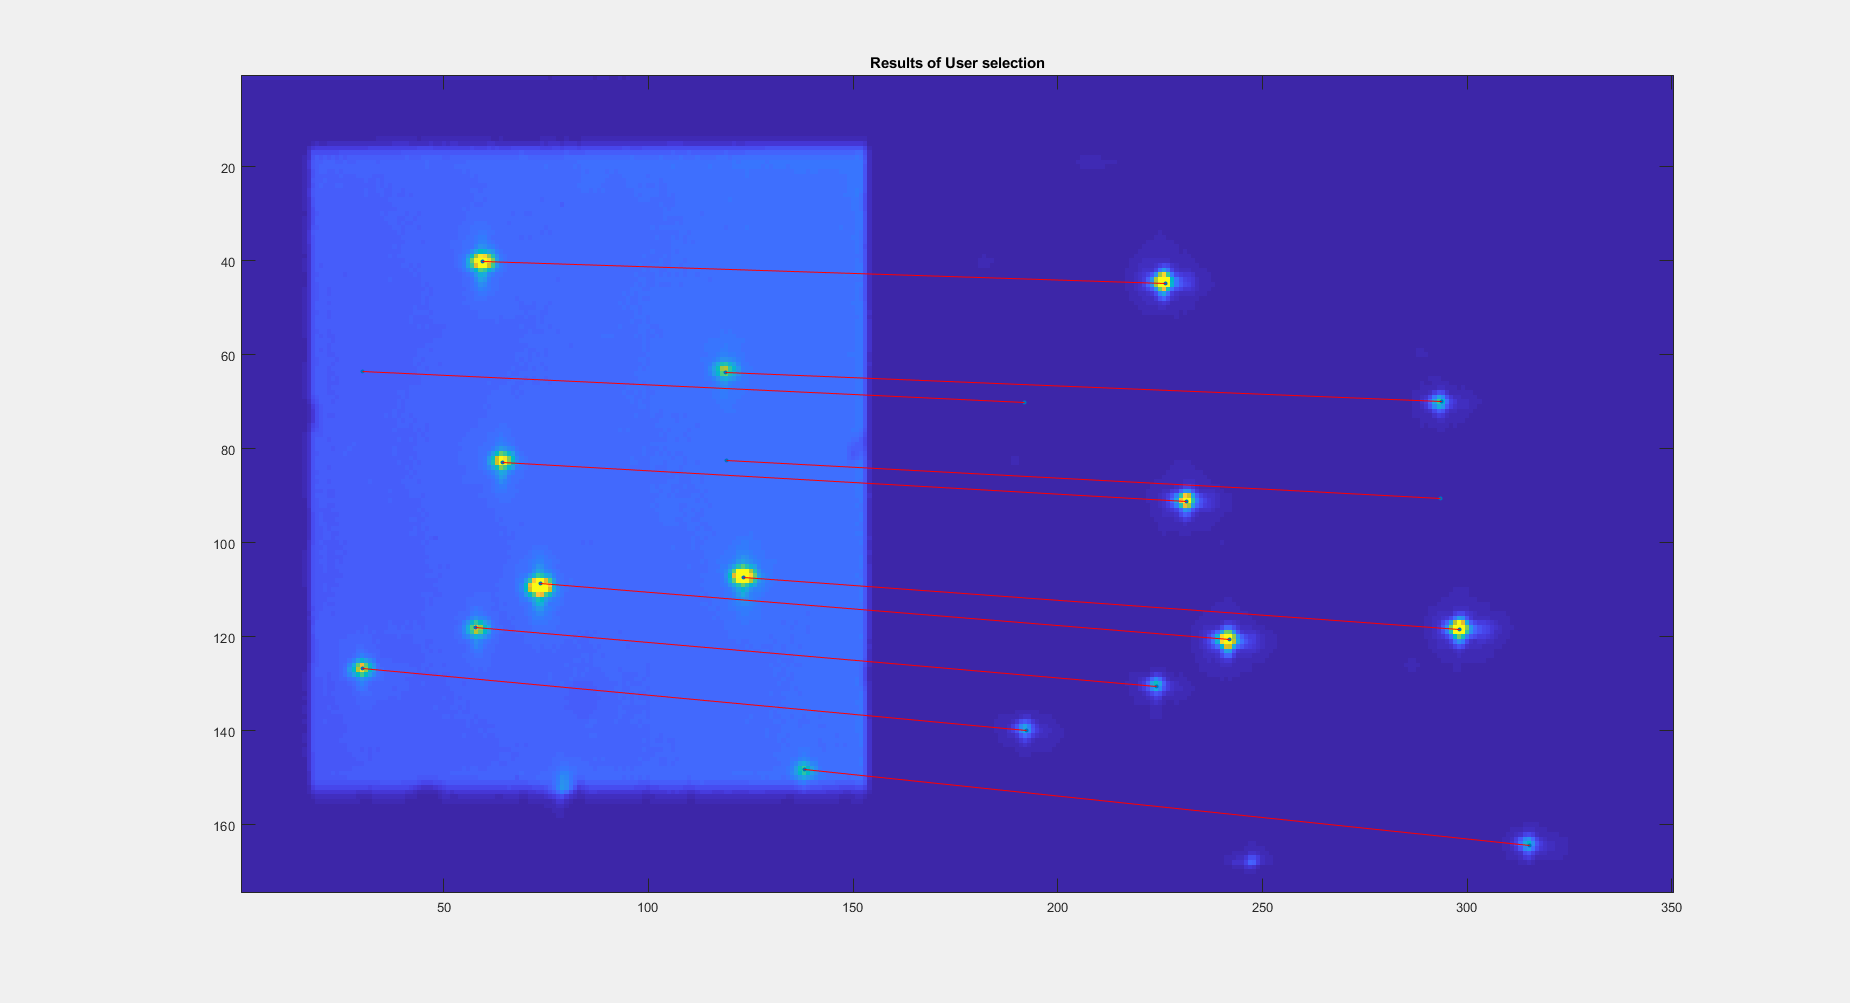

% Show selected points
imagesc(mean_image,clims)
hold on
scatter(x,y,10,'filled')
for i = 1:2:numel(x)
   plot(x(i:i+1),y(i:i+1),'r')
end
hold off
title('Results of User selection')

% Display results of file three overlaid onto average
file = 6;
% for file = 1:numel(files)
    files(file).name

Index exceeds the number of array elements (5).

    load(files(file).name)
    figure
imagesc(mean_image,clims)
hold on
plot(cdata.red.xf/cal.q,cdata.red.yf/cal.q,'.r');
plot(cdata.orange.xf/cal.q,cdata.orange.yf/cal.q,'.b');
% hold off
title('Results of localization fit')

plot(X,Y,'.r')



xo = [];
xr = [];
yo = [];
yr = [];
for i = 1:degrees
    % set up red,orange, red, orange
    xo = [xo; x(i*2)];
    xr = [xr; x((i-1)*2+1)];
    yo = [yo; y(i*2)];
    yr = [yr; y((i-1)*2+1)];
    
end

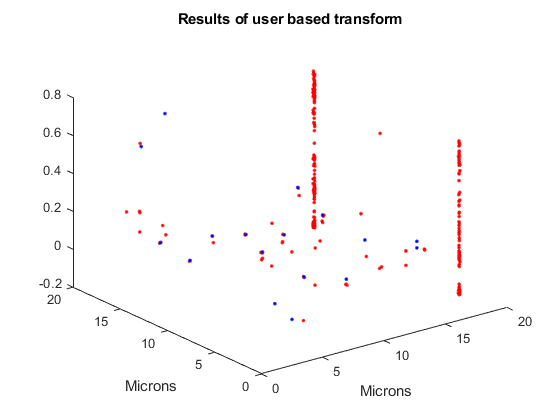

figure

MX = xy_feature(xo,yo);
MY = MX;
MX = [MX, xr(:)];
MY = [MY, yr(:)];
split = 171;
red_x = X(X < split);
red_z = Z(X < split);
orange_x = X(X > split);
red_y = Y(X < split);
orange_y = Y(X > split);
orange_z = Z(X > split);
similar_red = similar_file(X<split);
similar_orange = similar_file(X>split);
MX = rref(MX);
MY=  rref(MY);
o2rx = MX(:,end);
o2ry = MY(:,end);
orange_vector = xy_feature(orange_x,orange_y);
x_orange = o2rx.'*orange_vector.';
y_orange = o2ry.'*orange_vector.';
q = cal.q;
plot3(red_x*q,q*red_y,q*red_z,'.r')
ylabel('Microns')
hold on
plot3(x_orange*q,q*y_orange,q*orange_z,'b.')
xlabel('Microns')
title('Results of user based transform')
hold off

% Automatic pair analysis given initial seeding
pair = x_orange*0;
x_pair = [];
y_pair = [];
z_pair = [];
for i = 1:numel(x_orange)
    index = find(similar_red == similar_orange(i));

    dists = ((red_x(index) - x_orange(i)).^2 + (red_y(index) - y_orange(i)).^2).^0.5;
    closest = find(dists == min(dists));
    dists(closest);
    if dists(closest) < 5
        x_pair = [x_pair; [x_orange(i), red_x(index(closest)), orange_x(i)]];
        y_pair = [y_pair; [y_orange(i), red_y(index(closest)), orange_y(i)]];
        z_pair = [z_pair; [orange_z(i), red_z(index(closest)), orange_z(i)]];
        
    end
end

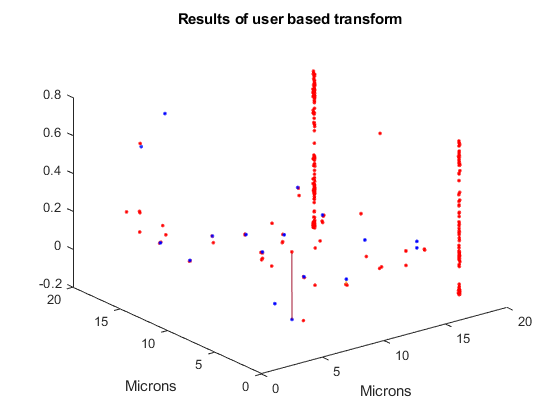

% convifrmation of pair analysis
plot3(q*red_x,q*red_y,q*red_z,'.r')
hold on

plot3(x_orange*q,q*y_orange,q*orange_z,'b.')
% plot(orange_x*q,q*orange_y,'.b')

for i = 1:numel(x_pair(:,1))
    plot3(q*x_pair(i,1:2),q*y_pair(i,1:2),q*z_pair(i,1:2))
end
hold off
xlabel('Microns')
title('Results of user based transform')
ylabel('Microns')

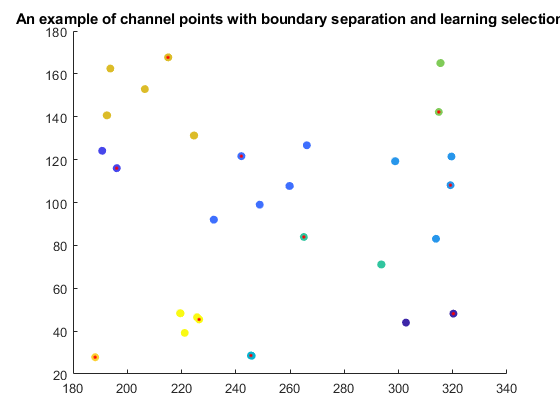

% k means cluster over a field
% Performing cluster over the pair variable allows us to implement cluster
% data onto the established relationships
data = [x_pair(:,3),y_pair(:,3)];
cluster_id = kmeans(data,degrees);
scatter(data(:,1),data(:,2),[],cluster_id,'filled')
for i = 1:degrees
    relevant_molecules = find(cluster_id == i);
    random_index = randi(numel(relevant_molecules),1);
%     Assign random molecule around the picture to a training set
    % To perform the transform we're going to want a list 
    xo(i) = x_pair(relevant_molecules(random_index),3);
    yo(i) = y_pair(relevant_molecules(random_index),3);
    xr(i,1) = x_pair(relevant_molecules(random_index),2);
    yr(i,1) = y_pair(relevant_molecules(random_index),2);
end
hold on
plot(xo,yo,'.r')
hold off
title('An example of channel points with boundary separation and learning selection')

MX = xy_feature(xo,yo);
MY = xy_feature(xo,yo);
MX = [MX,xr];
MY = [MY,yr];
MX = rref(MX)

MX =     1.0000         0         0         0         0         0         0         0         0         0   -0.0000
         0    1.0000         0         0         0         0         0         0         0         0    0.0000
         0         0    1.0000         0         0         0         0         0         0         0    0.0000
         0         0         0    1.0000         0         0         0         0         0         0   -0.0000
         0         0         0         0    1.0000         0         0         0         0         0    0.0014
         0         0         0         0         0    1.0000         0         0         0         0   -0.0001
         0         0         0         0         0         0    1.0000         0         0         0   -0.0007
         0         0         0         0         0         0         0    1.0000         0         0    0.5677
         0         0         0         0         0         0         0         0    1.0000         0    0.1

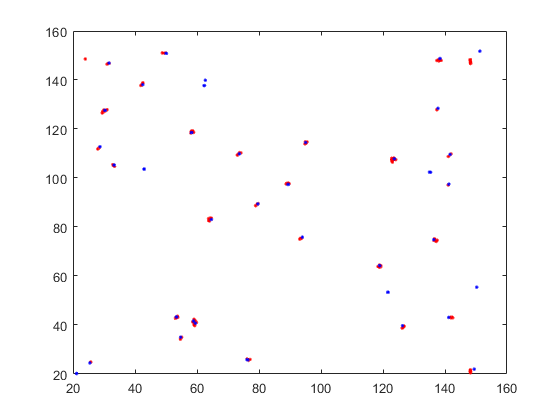

MY = rref(MY);
o2rx = MX(:,end);
o2ry = MY(:,end);
figure
plot(red_x, red_y, '.r');
data_vector = xy_feature(orange_x,orange_y);
x_orange = o2rx.'*data_vector.';
y_orange = o2ry.'*data_vector.';
hold on
plot(x_orange,y_orange,'.b')
hold off

% Right now best bet appears to be iterate the above manually to decide on
% an ideal calibration
close all

% net.numOutputs = 1;
randomizaiton_index = randperm(numel(x_pair(:,3)));
o = numel(randomizaiton_index);
train_percentage = 0.7;
 inputs = [x_pair(randomizaiton_index(1:round(o*train_percentage)),3),y_pair(randomizaiton_index(1:round(o*train_percentage)),3)]';
outputs = [x_pair(randomizaiton_index(1:round(o*train_percentage)),2),y_pair(randomizaiton_index(1:round(o*train_percentage)),2)]';
% nnstart
net1 = get_channel_net_solution(inputs,outputs)


net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 52
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inp

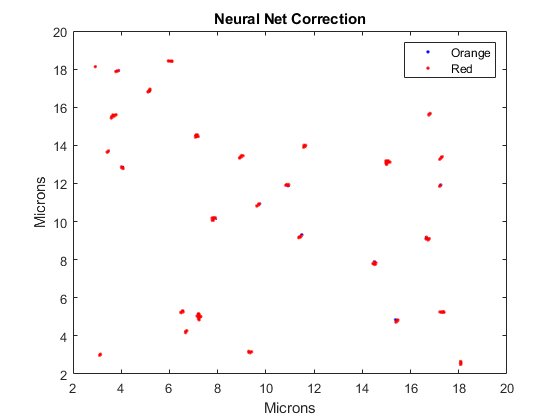

comp_name = get_computer_name();
% load([comp_name,'\Documents\GitHub\Matlab-Master\2-Channel Codes\2_color_neural_net.mat'],'net1','x_pair','y_pair', 'split')
new_outs = net1(inputs);
plot(new_outs(1,:)*q,q*new_outs(2,:),'.b')
hold on
plot(red_x*q, q*red_y,'.r')
hold off
legend('Orange','Red')
title('Neural Net Correction')
xlabel('Microns')
ylabel('Microns')

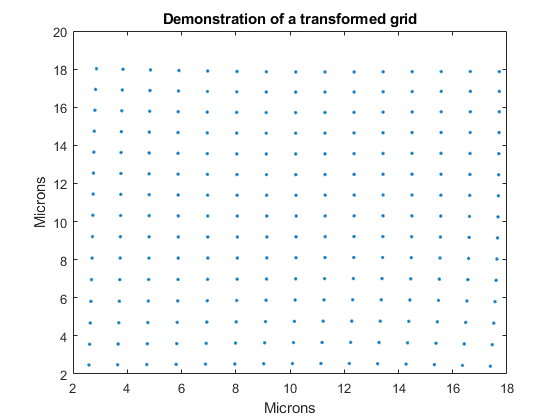

% Running new neural net through it's paces
[X_grid,Y_grid] = meshgrid(min(orange_x):10:max(orange_x),min(orange_y):10:max(orange_y));
inputs = [X_grid(:), Y_grid(:)]';
outputs = net1(inputs);
plot(outputs(1,:)*q,q*outputs(2,:),'.')
title('Demonstration of a transformed grid')
xlabel('Microns')
ylabel('Microns')

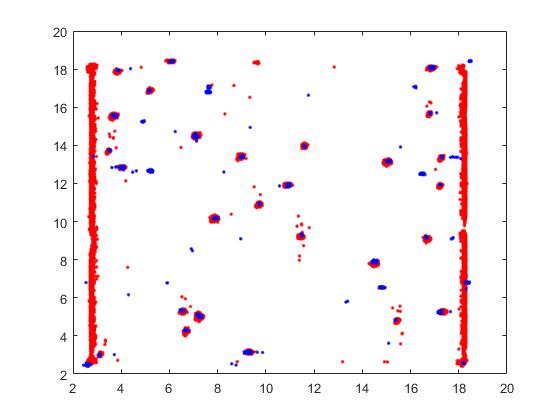

% demonstration of 2 color registration over all data 
% input = [xf(xf > 171), yf(xf >171)].';
cdata.orange.xf = xf(xf>180);
cdata.orange.yf = yf(xf>180);
cdata.orange.zf = cdata.orange.xf *0;
cdata.red.xf = xf(xf<180);
cdata.red.yf = yf(xf<180);
cdata.red.zf = cdata.red.xf *0;


input = [cdata.orange.xf,cdata.orange.yf].';
output = net1(input);
plot(cdata.red.xf*q,cdata.red.yf*q,'.r')
hold on
plot(output(1,:)*q, q*output(2,:),'.b')
hold off

comp_name = get_computer_name();
% save([comp_name,'\Documents\GitHub\Matlab-Master\2-Channel Codes\2_color_neural_net.mat'],'net1','x_pair','y_pair', 'split')
save('2_color_neural_net.mat','net1','x_pair','y_pair', 'split')

[x_out, y_out] = make_nn_channel_transform(xf(xf > 171)*q, q*yf(xf >171));
plot(xf(xf < 171)*q, q*yf(xf<171),'.r')
hold on
plot(x_out,y_out,'.b')
xlabel('Microns')
ylabel('Microns')
title('All localizations transformed')
legend('Red','Orange')
hold off